% EDP tutorial with a 2d example
% clear all
close all
rng('default');
rng(1);

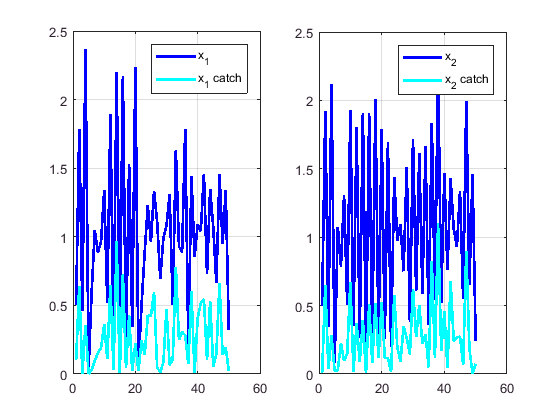

% time-series generation
T = 50;

% default EDM structure
[mdlstruct] = init_mdl_struct(2); % the input is the number of species

% data generation using a ricker model
param={[0.1 0.1],[3 0.5; 0.4 3],[3 3]}; % ricker model parameters
mdlstruct.model = @(x,u,is_det) dyn_ricker(x,u,is_det,param);


% random control
u = rand(T,2)/2;

% data generation
[mdlstruct.data,mdlstruct.control_data] =  generate_data(mdlstruct.model,[0.5 0.5],u,T);

%different kinds of control exist, we need to specify which one we use here
mdlstruct.control_type =  'rate';
mdlstruct.control_param =  [1 1]; % both  dimensions are controlled

% data display
data_show(mdlstruct)

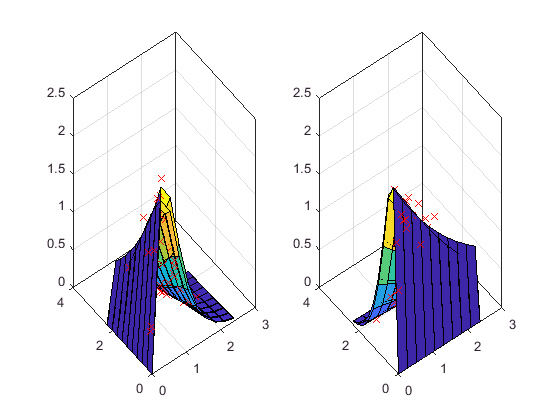

% gp regression
% this step can be skipped if a model already exists, otherwise a GP is
% fitted to the data
% fills the field mdlstruct.model with the fitted gp
% fills the field mdlstruct.model_stats with statistics computed during the
% GP regression

% default gp structure
mdlstruct.gp = init_gp();

% we now fit the gp with the data in mdlstruct
mdlstruct = fit_gp(mdlstruct);


gp_show(mdlstruct)

% optimal control problem
% Discount factor
optstruct.discount_factor=0.95;

% Objective weights
optstruct.weights = [0.5 0.5];


% Reward function
% The instantaneous reward function is a handle function.
% The input are the current variables, the controls and the weight for each
% dimension
% The output are the total weighted reward, the unweighted reward on each
% dimension, and the weighted reward on each dimension

%>>> Example 1 <<<<
% use of an existing function
optstruct.reward = @(x,u) reward_harvest_all(x,u,optstruct.weights);

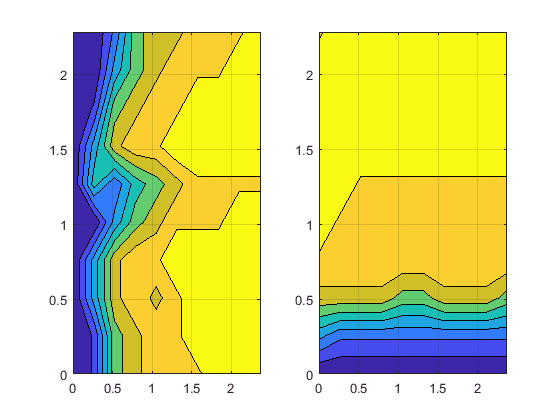

% temporal difference learning

% default  td structure
dpstruct=init_td(mdlstruct);

%  run the td algorithm, using the gp regression
 [dpstruct] = td_learning(mdlstruct,optstruct,dpstruct,'gp');

 % control maps
td_show(mdlstruct,optstruct,dpstruct)

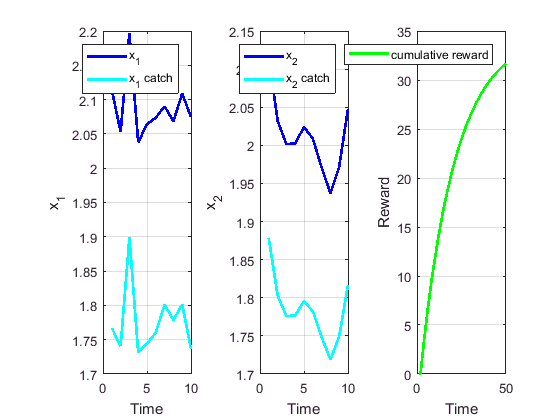


% controlled trajectories
t_max = 50;
n_traj = 10;
start_x = 'last';
traj = sim_trajectories(mdlstruct,optstruct,dpstruct,t_max,n_traj,start_x);

dpstruct10 = struct with fields:
                              method: 'td'
                    n_support_states: 50
    generating_support_states_method: 'random'
                      support_states: [50×2 double]
                              lambda: 0.5000
                           n_out_max: 20
                            n_in_max: 2
                               debug: 0
                               model: @(x,u,is_det)dyn_ricker(x,u,is_det,param)
                        control_grid: [100×2 double]
                      value_function: [1×1 struct]


dpstruct01 = struct with fields:
                              method: 'td'
                    n_support_states: 50
    generating_support_states_method: 'random'
                      support_states: [50×2 double]
                              lambda: 0.5000
                           n_out_max: 20
                            n_in_max: 2
                               debug: 0
                               model: @(x,u,is_det)dyn_ricker(x,u,is_det,param)
                        control_grid: [100×2 double]
                      value_function: [1×1 struct]


Error using reshape
To RESHAPE the number of elements must not change.

Error in td_learning (line 131)
        [fTD,indCurrentU]=min(reshape(ftd,length(control_grid),length(currentX)));

Error in pareto_front (line 29)
    [dpstruct] = td_learning(mdlstruct,optstruct,dpstruct,'mdl')

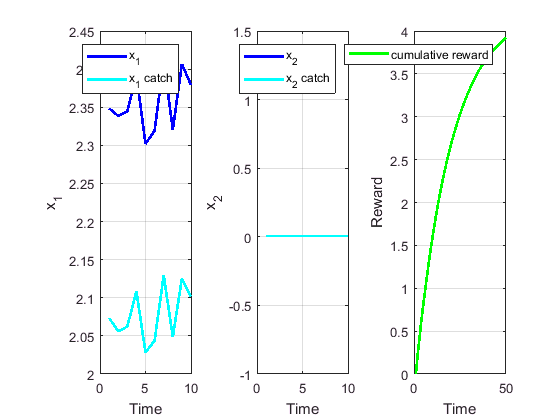

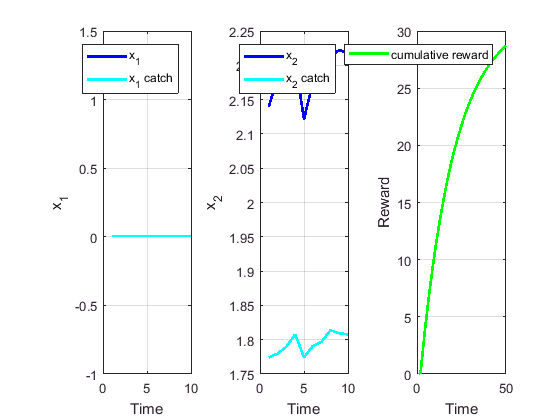


% Pareto front
n_pareto = 10;
pareto = pareto_front(mdlstruct,optstruct,dpstruct,n_pareto);